# Record your voice

Record the sentence: "Hello ... is it me your looking for ?" using 48000 sample rate. Please try to enunciate clearly as if you are a BBC announcer. We will use this sentence in further work.

% you should use the code below to record audio
recTime = 6.0 ; % seconds
devId = 3 ; % microphone
%device
fs = 48000 ; % I like to use 48 kHz
bufSiz = 2048 ; 
userStart = true ; % Have to press return to start recording

recSig = RecordAudio(recTime, devId, fs, bufSiz, userStart) ;

Press a key to start recording


You can then select a restricted portion of the signal which removes the rubbish at the start and end of the signal, plot the signal first:

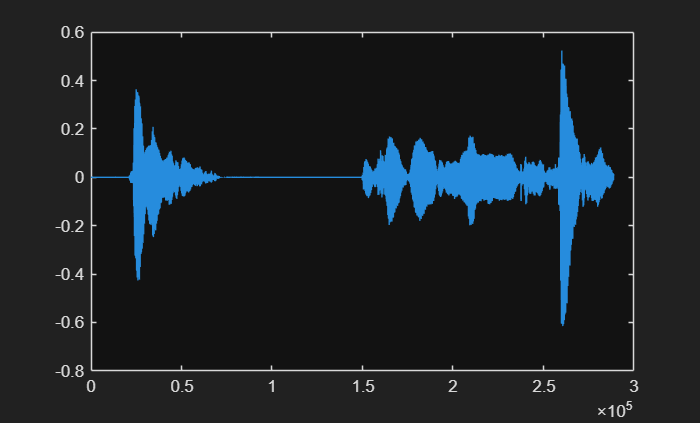

% Plot signal
figure ;
plot(recSig) % x-axis is the sample number
set(gcf,'Visible','On')

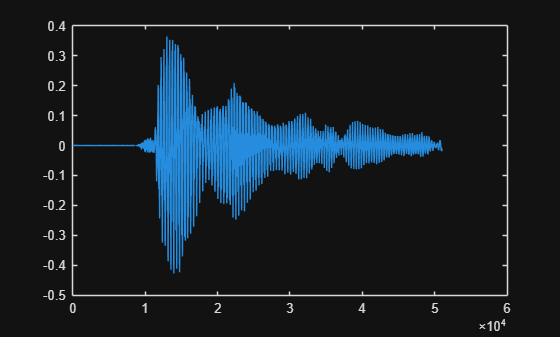

recSigWin = recSig(12000:63000) ;
% plot the windowed signal
figure ;
plot(recSigWin)

## 1. Truncated Ideal Low-Pass Filter

Create an ideal truncated low-pass filter based on the following formula


$$H(e^{j\,\omega}) = \left\{\begin{array}{ll}
1\cdot e^{-j\,\alpha\,\omega}\text{,} & |\omega| \lt \omega_c \\
0\text{,} & \omega_c < |\omega| \le \pi
\end{array}$$


## Compute the Analytic Solution for the impulse response below:


$$h(n) = \frac{1}{2\,\pi}\int_{-\omega_c}^{\omega_c}e^{-j\,\alpha\,\omega}e^{j\,n\,\omega}d\omega = \frac{1}{2\,\pi}\frac{e^{j\,(n-\alpha)\,\omega}}{j\,(n-\alpha)}|_{-\omega_c}^{\omega_c} = \frac{\sin\left[\omega_c\,(n-\alpha)\right]}{\pi\,(n-\alpha)$$


Determine and plot the truncated impulse response 


$$h[n] \ \text{for} \ 0 \le n < N-1$$


using N = 61, $\alpha = 30$. Choose $\omega_c$ so that the cut-off frequency is 1500 Hz.

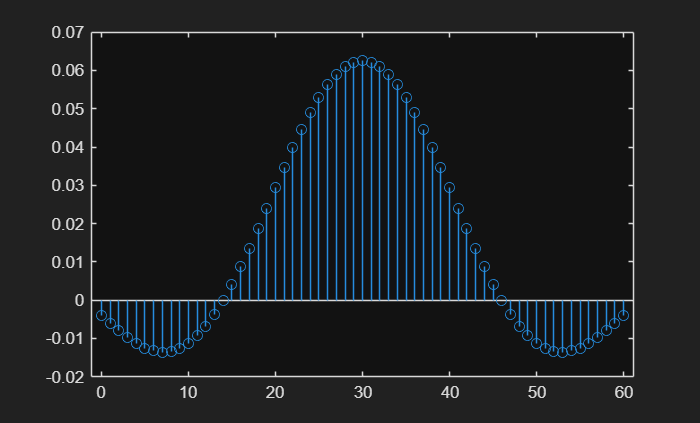

% Put your code here
n = 0:60;                    % N = 61 points, 0 to N-1
alpha = 30;                  % delay (centre of filter)
fs = 48000;                  % what you used to record the audio
wc = 2 * pi * 1500 / fs;     % normalised cutoff for 1500 Hz

% Since: sinc(pi x) = sin(pi x)/(pi x)

% Hence: sin(wc*(n-alpha))/(pi*(n-alpha)) = (wc/pi) * sinc(wc*(n-alpha)/pi)

lpFilt = (wc/pi) * sinc(wc*(n-alpha)/pi);

figure;
set(gcf,'Visible','On')
stem(n, lpFilt)

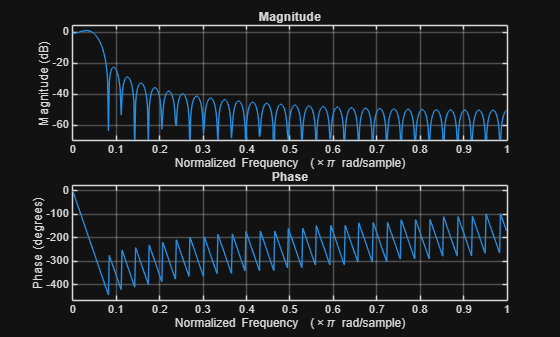

figure
freqz(lpFilt, 1)

`freqz(lpFilt, 1)`

`Computes and plots the frequency response of a digital filter `

`Here's what the arguments mean:`

`lpFilt → the filter coefficients (numerator, i.e. FIR filter) `

`1 → denominator coefficients (since it's an FIR filter, denominator = 1)`

### Apply low-pass filter to the windowed voice signal

lpSig = filter(lpFilt,1,recSigWin) ;
soundsc(lpSig,fs)

## 2.Truncated Ideal High-Pass Filter

Create an ideal truncated high-pass filter based on the following formula


$$H(e^{j\,\omega}) = \left\{\begin{array}{ll}
1\cdot e^{-j\,\alpha\,\omega}\text{,} & \omega_c < |\omega| \le \pi \\
0\text{,} & |\omega| \le \omega_c
\end{array}$$


## Compute the Analytic Solution for the impulse response below:

Show your work using latex equations below.

Put work here:


$$h(n) = \frac{1}{2\,\pi}\int_{-\pi}^{-\omega_c}e^{j\,\omega(n-\alpha)}d\omega + \frac{1}{2\,\pi}\int_{\omega_c}^{\pi}e^{j\,\omega(n-\alpha)}d\omega$$



$$h(n) = \frac{1}{2\,\pi}\int_{-\pi}^{\pi}e^{j\,\omega(n-\alpha)}d\omega - \frac{1}{2\,\pi}\int_{-\omega_c}^{\omega_c}e^{j\,\omega(n-\alpha)}d\omega$$



$$h(n) = \frac{\sin\left(\pi(n-\alpha)\right)}{\pi(n-\alpha)} -  \frac{\sin\left(\omega_c(n-\alpha)\right)}{\pi(n-\alpha)}$$



$$h[n] = \text{sinc}(n-\alpha)-\frac{\omega_c}{\pi}\text{sinc}\left(\frac{\omega_c}{\pi}(n-\alpha)\right)$$


Determine and plot the truncated impulse response 


$$h[n] \ \text{for} \ 0 \le n < N-1$$


using N = 61, $\alpha = 30$. Choose $\omega_c$ so that the cut-off frequency is 2500 Hz.

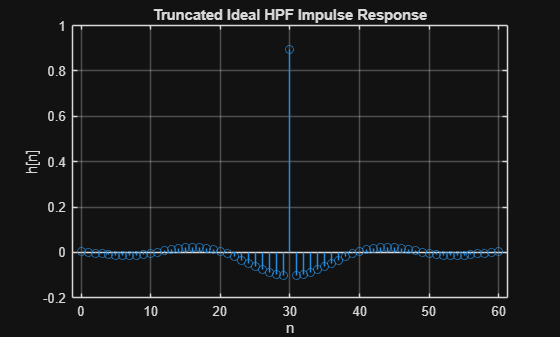

fs = 48000;
Ntaps = 61;
n = (0:Ntaps-1);
alpha = 30;
wc = 2 * pi * 2500 / fs;     % normalised cutoff for 2500 Hz

% sinc(n-alpha) is the allpass (delta shifted), minus the LPF gives HPF

% h[n] = sinc(n-alpha) - (wc/pi)*sinc(wc/pi*(n-alpha))

hpFilt = sinc(n - alpha) - (wc/pi) * sinc(wc/pi * (n - alpha));

figure;
stem(n, hpFilt)
xlabel('n')
ylabel('h[n]')
title('Truncated Ideal HPF Impulse Response')
grid on

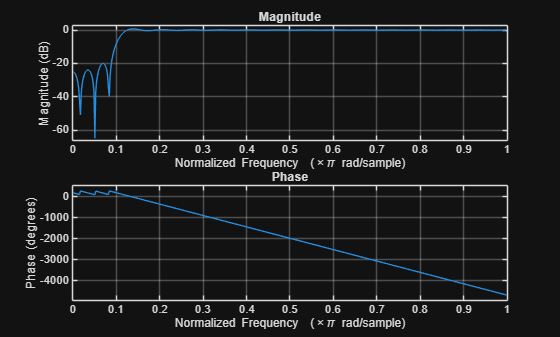

figure;
freqz(hpFilt, 1)

### Apply high-pass filter to the windowed voice signal

hpSig = filter(hpFilt,1,recSigWin) ;
soundsc(hpSig,fs)

# Positive and Negative Frequencies

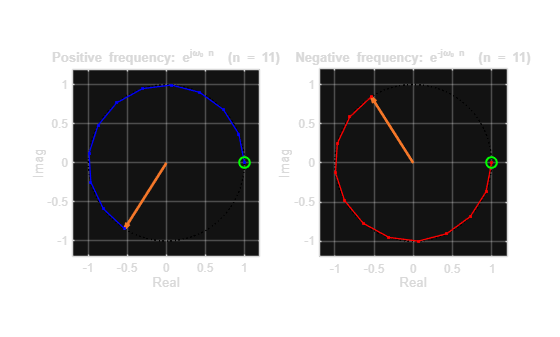

N = 12;
n = 0:N-1;
w0 = 0.12*pi;

% Create positive frequency component e^(j w0 n)
xp = exp(1j * w0 * n);       % positive frequency - rotates anticlockwise

% Create negative frequency component e^(-j w0 n)
xn = exp(-1j * w0 * n);      % negative frequency - rotates clockwise

figure('Color','w');

for k = 1:N
    subplot(1,2,1);
    cla;
    th = linspace(0,2*pi,400);
    plot(cos(th), sin(th), 'k:'); hold on;              % unit circle
    quiver(0, 0, real(xp(k)), imag(xp(k)), 0, ...
        'LineWidth', 2, 'MaxHeadSize', 0.3);
    plot(real(xp(1:k)), imag(xp(1:k)), 'b.-', 'LineWidth', 1);
    plot(real(xp(1)), imag(xp(1)), 'go', 'MarkerSize', 8, 'LineWidth', 1.5);
    axis equal; axis([-1.2 1.2 -1.2 1.2]); grid on;
    xlabel('Real'); ylabel('Imag');
    title(sprintf('Positive frequency: e^{j\\omega_0 n}  (n = %d)', k-1));

    subplot(1,2,2);
    cla;
    plot(cos(th), sin(th), 'k:'); hold on;
    quiver(0, 0, real(xn(k)), imag(xn(k)), 0, ...
        'LineWidth', 2, 'MaxHeadSize', 0.3);
    plot(real(xn(1:k)), imag(xn(1:k)), 'r.-', 'LineWidth', 1);
    plot(real(xn(1)), imag(xn(1)), 'go', 'MarkerSize', 8, 'LineWidth', 1.5);
    axis equal; axis([-1.2 1.2 -1.2 1.2]); grid on;
    xlabel('Real'); ylabel('Imag');
    title(sprintf('Negative frequency: e^{-j\\omega_0 n}  (n = %d)', k-1));

    drawnow;
    pause(0.06);
end

# Generalised Linear Phase FIR Filters

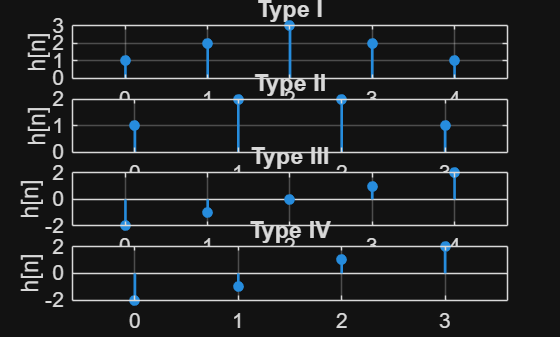

% Type I: symmetric, odd length
h1 = [1 2 3 2 1];

% Type II: symmetric, even length
h2 = [1 2 2 1];

% Type III: antisymmetric, odd length
h3 = [-2 -1 0 1 2];

% Type IV: antisymmetric, even length
h4 = [-2 -1 1 2];

Hs = {h1,h2,h3,h4};
names = {'Type I','Type II','Type III','Type IV'};

figure;
for k = 1:4
    subplot(4,1,k);
    h = stem(0:length(Hs{k})-1, Hs{k}, 'filled');
    
    % Thicker stems
    h.LineWidth = 2;
    h.MarkerSize = 6;

    grid on;
    xlabel('n'); 
    ylabel('h[n]');
    title(names{k});

    % Increase axis font size
    ax = gca;
    ax.FontSize = 16;   % try 18, 20, etc. for even larger
end

- TYPE I     : Symmetrical & odd

- TYPE II    : Symmetrical & even

- TYPE III   : Asymmetrical & odd

- TYPE IV   : Asymmetrical & even

## Compute the Magnitude and Phase Spectrum of the FIR Filters

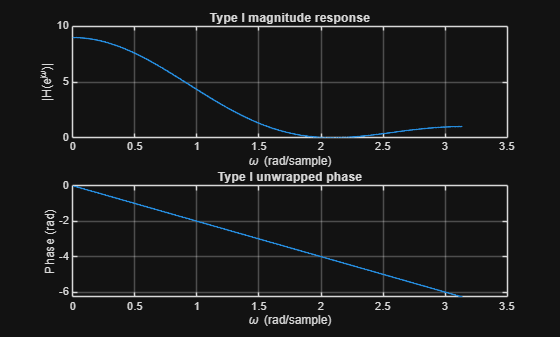

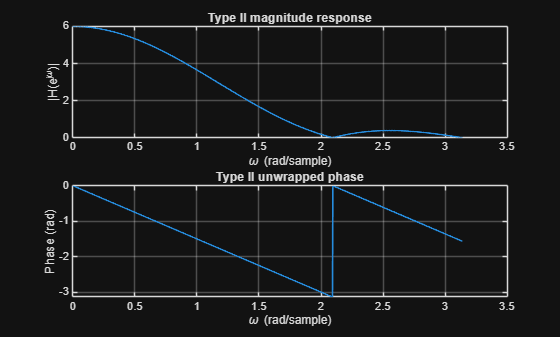

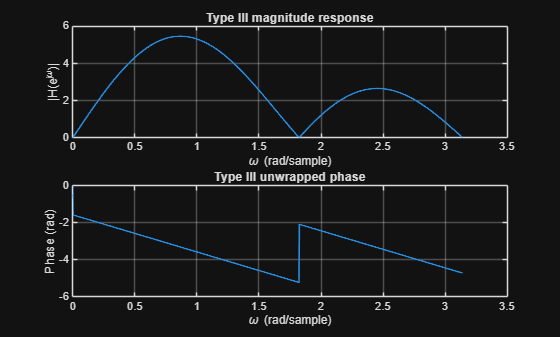

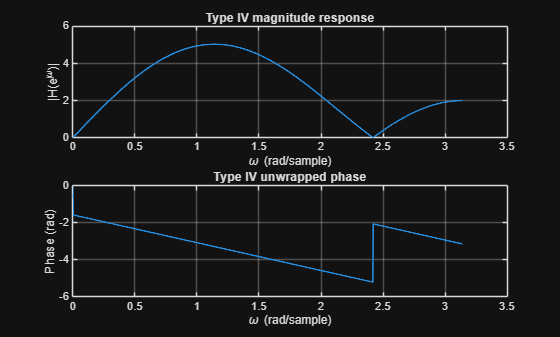

h1 = [1 2 3 2 1];
h2 = [1 2 2 1];
h3 = [-2 -1 0 1 2];
h4 = [-2 -1 1 2];

Hs = {h1,h2,h3,h4};
names = {'Type I','Type II','Type III','Type IV'};

for k = 1:4
    % Use freqz function freqz(b's,1,1024)
    [H,w] = freqz(Hs{k}, 1, 1024);

    % Compute magnitude spectrum
    mag = abs(H);

    % Compute phase spectrum (unwrapped)
    ph = unwrap(angle(H));
    
    figure;
    subplot(2,1,1);
    plot(w, mag, 'LineWidth', 1.2);
    grid on;
    xlabel('\omega (rad/sample)');
    ylabel('|H(e^{j\omega})|');
    title([names{k} ' magnitude response']);
    
    subplot(2,1,2);
    plot(w, ph, 'LineWidth', 1.2);
    grid on;
    xlabel('\omega (rad/sample)');
    ylabel('Phase (rad)');
    title([names{k} ' unwrapped phase']);
end

## Check DC and Nyquist Frequency

h1 = [1 2 3 2 1];
h2 = [1 2 2 1];
h3 = [-2 -1 0 1 2];
h4 = [-2 -1 1 2];

Hs = {h1,h2,h3,h4};
names = {'Type I','Type II','Type III','Type IV'};

for k = 1:4
    h = Hs{k};
    % Compute H(omega = 0) — e^(j*0*n) = 1, so just sum all coefficients
    H0  = sum(h);                           % H(e^j0)

    % Compute H(omega = pi) — e^(j*pi*n) = (-1)^n, so alternating sum
    n   = 0:length(h)-1;
    Hpi = sum(h .* (-1).^n);               % H(e^jpi)
    
    fprintf('%s\n', names{k});
    fprintf('  H(0)   = %g\n', H0);
    fprintf('  H(pi)  = %g\n\n', Hpi);
end

Type I


  H(0)   = 9


  H(pi)  = 1



Type II


  H(0)   = 6


  H(pi)  = 0



Type III


  H(0)   = 0


  H(pi)  = 0



Type IV


  H(0)   = 0


  H(pi)  = -2



## Hilbert Transformers and Differentiators

A Hilbert transformer ideally has frequency response:


$$H(e^{j\omega}) =
\begin{cases}
-j, & 0 < \omega < \pi \\
+j, & -\pi < \omega < 0
\end{cases}$$


which is purely imaginary and odd in frequency.

A differentiator has frequency response proportional to:


$$j \omega$$


which is odd and imaginary.

#### These are naturally realised by antisymmetric impulse responses.

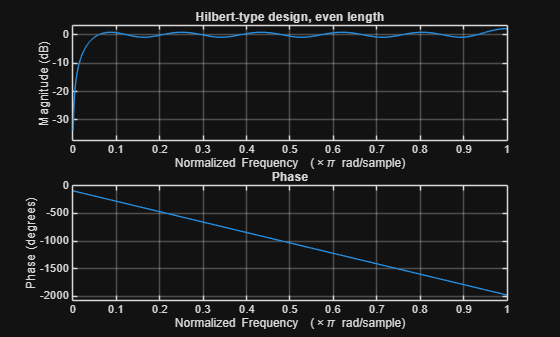

N3 = 20;   % order 20 => length 21 => odd length, likely Type III for hilbert-like
b3 = firpm(N3, [0.05 0.95], [1 1], 'hilbert');

N4 = 21;   % order 21 => length 22 => even length, likely Type IV
b4 = firpm(N4, [0.05 0.95], [1 1], 'hilbert');

figure;
subplot(2,1,1); freqz(b3,1,1024); title('Hilbert-type design, odd length');
subplot(2,1,2); freqz(b4,1,1024); title('Hilbert-type design, even length');

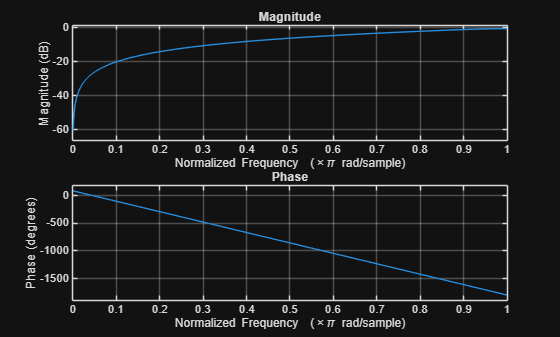

Nd = 21;
bd = firpm(Nd, [0 0.9], [0 0.9], 'differentiator');
freqz(bd,1,1024);

firpm() designs an optimal linear‑phase FIR filter using the Parks–McClellan (Remez) equiripple algorithm.

Input summary: b = firpm(n, f, a, w)

- n: filter order (length = n+1)

- f: band-edge frequencies (0..1, where 1 = Nyquist)

- a: desired amplitudes at those edges

- w (optional): relative weights for each band

## Group Delay - Compute for a Low-Pass Filter

Suppose the phase response is not exactly linear, but we examine a narrow frequency band around some frequency $\omega_0$. Then we can approximate the phase locally by its tangent line: $\phi(\omega)\approx \phi(\omega_0)+\phi'(\omega_0)(\omega-\omega_0)$.


$$\phi(\omega)\approx
\underbrace{\bigl(\phi(\omega_0)-\omega_0\phi'(\omega_0)\bigr)}_{\text{constant phase term}}
+
\omega\,\phi'(\omega_0).$$


This has exactly the same form as the linear-phase expression for a delayed sinusoid. Comparing with

$\phi(\omega)=-\omega \delta t,$ we identify the local delay as $\delta t = -\phi'(\omega_0).$

Since this delay depends on the frequency around which we linearize, we define the Group Delay at frequency $\omega$ by:


$$\tau_g(\omega)=-\frac{d\phi(\omega)}{d\omega}.$$


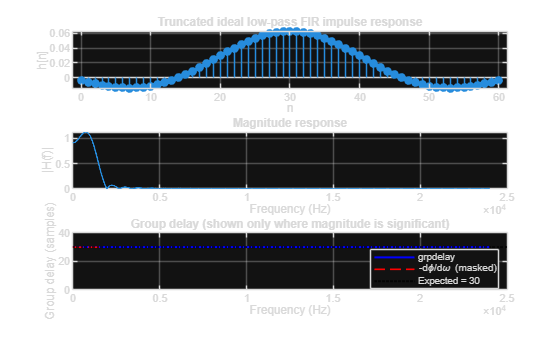

n = 0:60;
alpha = 30;
fs = 48000;
wc = (1500/(fs/2))*pi;

lpFilt = (wc/pi) * sinc((wc/pi)*(n-alpha));

% Frequency response
[H,w] = freqz(lpFilt,1,4096,fs);
magH = abs(H);                % Magnitude
phiH = unwrap(angle(H));      % Phase

% Built-in group delay
[gd_builtin,wg] = grpdelay(lpFilt,1,4096,fs);

% Numerical group delay:
% convert frequency in Hz to omega in rad/sample
% Compute omega from w (convert Hz → rad/sample)
omega = 2 * pi * w / fs;

% Compute the group delay using diff to approximate differentials
gd_num = -diff(phiH) ./ diff(omega);

% MUST define w_mid and mask right after — same length as gd_num
w_mid = w(1:end-1);                              % length 4095, matches gd_num
mask  = magH(1:end-1) > 0.1 * max(magH);        % length 4095, matches gd_num
figure('Color','w');

subplot(3,1,1);
stem(n, lpFilt, 'filled');
grid on;
xlabel('n');
ylabel('h[n]');
title('Truncated ideal low-pass FIR impulse response');

subplot(3,1,2);
plot(w, magH, 'LineWidth', 1.2);
grid on;
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
title('Magnitude response');

subplot(3,1,3);
plot(wg, gd_builtin, 'b', 'LineWidth', 1.5); hold on;
plot(w_mid(mask), gd_num(mask), 'r--', 'LineWidth', 1.2);
yline(alpha, 'k:', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('Group delay (samples)');
title('Group delay (shown only where magnitude is significant)');
legend('grpdelay','-d\phi/d\omega (masked)','Expected = 30','Location','best');
ylim([0 40]);